clear all;

path_opt= readtable('traj_opt_09.csv');

path_opt_SlowSteer= readtable('traj_opt_steerT06.csv');



kappa_opt= readtable('kappa_opt_09.csv');

kappa_opt_SlowSteer= readtable('kappa_opt_steerT06.csv');


u= readtable('ctrl_inputs.csv');

u_SlowSteer= readtable('ctrl_inputs_steerT06.csv');


time= readtable('time.csv');


london_outer=readtable('bound_outer.csv');

london_inner=readtable('bound_inner.csv');

path_og= readtable('track_smooth.csv');

s_opt= readtable('length_opt.csv');

%close all;
num_start=1;
num_end= length(s_opt.x_S_opt)-1;
plot_num= num_start:num_end;

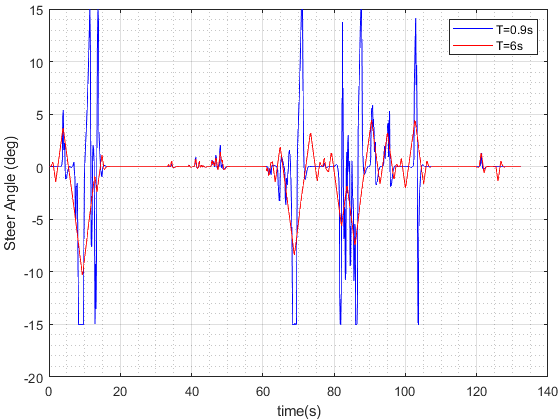

s_cumsum= cumsum(s_opt.x_S_opt);

figure;
plot(time.x_T_(1:940),rad2deg(u.x_Delta), "LineWidth", 0.5, "Color", "blue");
hold on;
plot(time.x_T_(1:940),rad2deg(u_SlowSteer.x_Delta), "LineWidth", 0.5, "Color", "red");
hold off
grid on; grid minor;
xlabel('time(s)')
ylabel('Steer Angle (deg)')
legend('T=0.9s', 'T=6s', "Location", 'Northeast')
set(gca,'LooseInset',get(gca,'TightInset'))

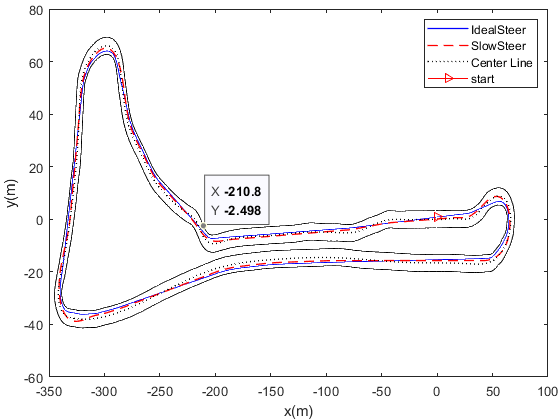

figure();
close;
plot(path_opt.x_Traj_x(plot_num), path_opt.traj_y(plot_num), 'blue', "LineWidth", 1.0)
hold on
plot(path_opt_SlowSteer.x_Traj_x(plot_num), path_opt_SlowSteer.traj_y(plot_num), 'red', "LineWidth", 1.0, "LineStyle","--")
hold on
plot(path_og.x_Track_x(plot_num), path_og.track_y(plot_num), 'black', "LineWidth", 1.0, "LineStyle",":")
hold on;
plot(path_opt.x_Traj_x(1), path_opt.traj_y(1), 'red', "marker",">")
hold on;
plot(london_outer.x_Outer_x, london_outer.outer_y, 'black', 'LineWidth', 0.5)
hold on;
plot(london_inner.x_Inner_x, london_inner.inner_y, 'black','LineWidth', 0.5)
hold off;
 
legend('IdealSteer', 'SlowSteer', 'Center Line', 'start', "Location", 'Northeast')
xlabel('x(m)');
ylabel('y(m)');
set(gca,'LooseInset',get(gca,'TightInset'))